# Machine Learning with MATLAB

Industrial AI & Automation  

# Classification with LDA, QDA

## Data Acquisition

### Dataset 1:  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

clear

%% Train
load("../CWRU_dataset/CWRU_features/example_train.mat");
feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
X(:, 1) = table2array(glob_all_train(:, feature1));
X(:, 2) = table2array(glob_all_train(:, feature2));
Y = class_cwru_train;       % fault class
N = size(X,1);
tbl=table(X(:, 1),X(:, 2),Y);


%% Test
load("../CWRU_dataset/CWRU_features/example_test.mat");
Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));
Ytest = class_cwru_test;                                 
Ntest=size(Xtest,1);
tblTest=table(Xtest(:, 1),Xtest(:, 2),Ytest);





#### Plot Test Data

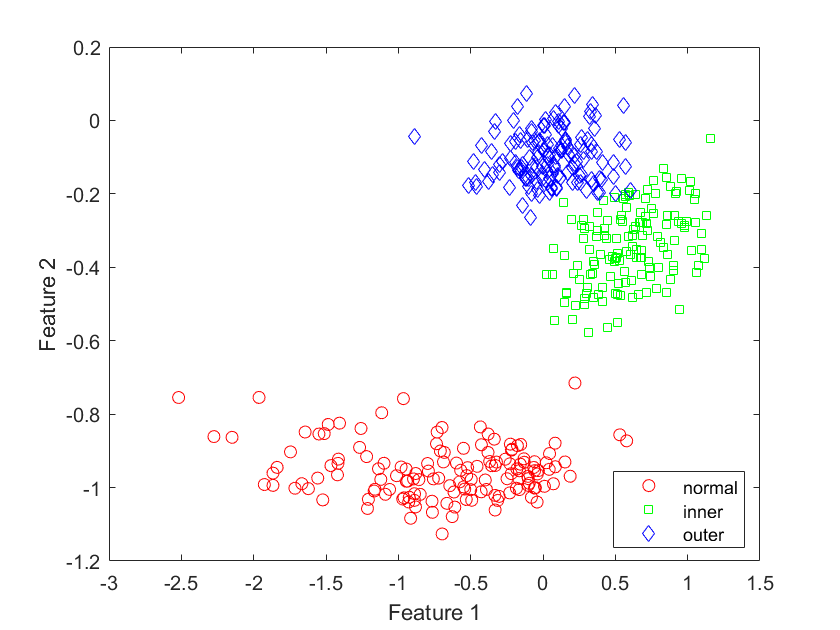

f = figure;
gscatter(X(:, 1), X(:, 2), Y,'rgb','osd');
xlabel('Feature 1')
ylabel('Feature 2')

## Prepare Cross-Validation Data

 `cvpartition` to generate 10 disjoint stratified subsets.

rng(0)
cv = cvpartition(Y,'KFold',10)  %k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

# LDA Classification 

fitdiscr()

### Classify with LDA **(Use all Data to train)**

lda = fitcdiscr(X,Y);

### **Anlayze **

**Resubstitution error**:  misclassification error  on the training set.

ldaResubErr = resubLoss(lda)

ldaResubErr = 0.0116

**Confusion matrix** on whole Data set

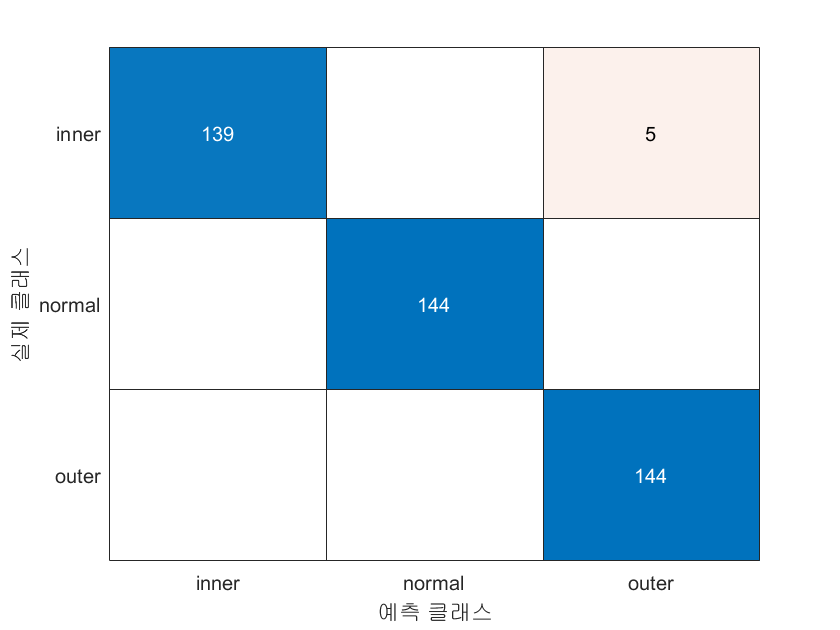

ldaClass = resubPredict(lda);

figure
ldaResubCM = confusionchart(Y,ldaClass);

**Misclassification Plot**

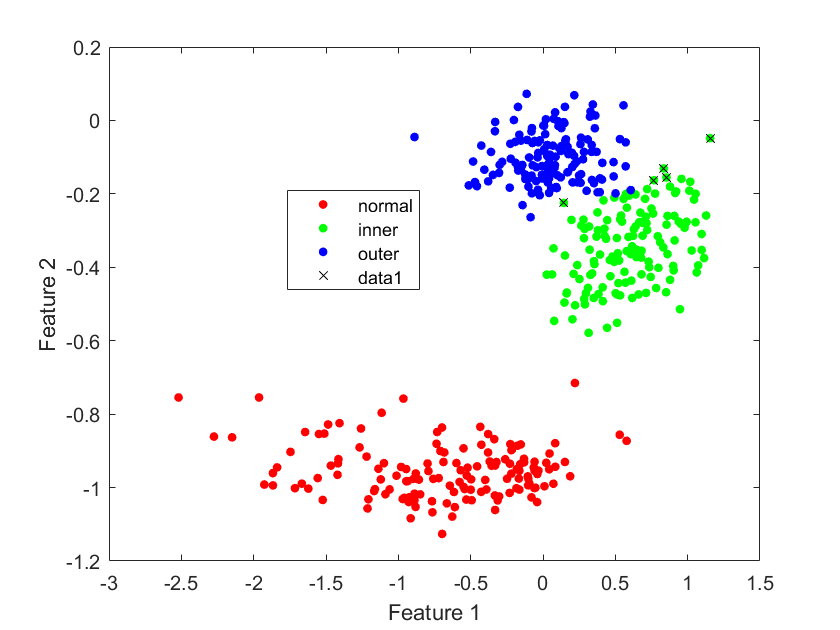

bad = ~strcmp(ldaClass,Y);

figure
gscatter(X(:,1),X(:,2),Y)
hold on;
plot(X(bad,1), X(bad,2), 'kx');
hold off;
xlabel('Feature 1')
ylabel('Feature 2')

**Visualize Separation regions **

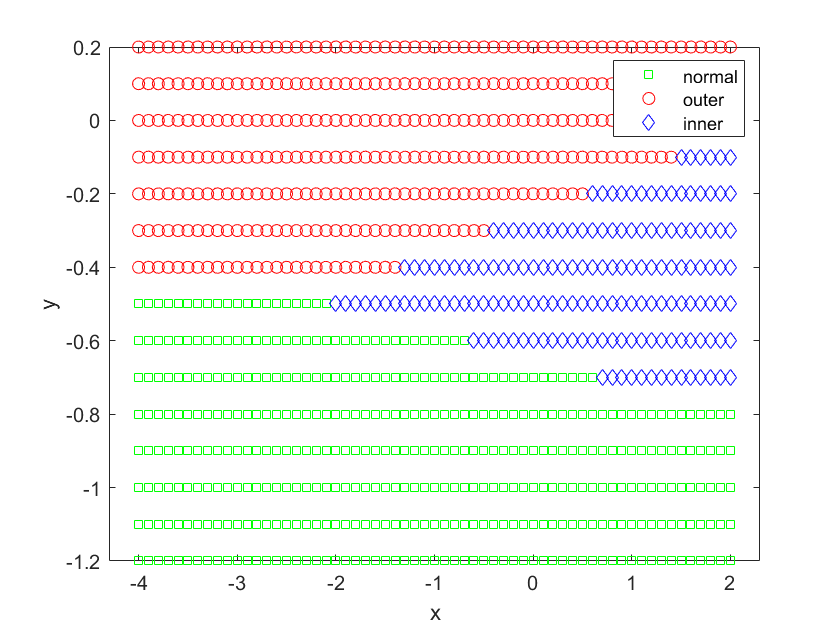

[x,y] = meshgrid(-4:.1:2,-1.2:.1:0.2);
x = x(:);
y = y(:);
j = classify([x y],X,Y);   % classify() for LDA / LQA. use predict(_) otherwise
gscatter(x,y,j,'grb','sod')

### **Validation (CV)**

Estimate the true test error for LDA using 10-fold stratified cross-validation.

cvlda = crossval(lda,'CVPartition',cv);
ldaCVErr = kfoldLoss(cvlda)  % loss on validation fold

ldaCVErr = 0.0139

### Classify with LDA (using CV-TrainSet)

% LDA Classify with CV-Train Set  70% Train, 30% Test
cp = cvpartition(N,"HoldOut",0.3);
trainInds = training(cp);
sampleInds = test(cp);
trainingData = X(trainInds,1:2);
sampleData = X(sampleInds,1:2);
trainingLabel= Y(trainInds);
sampleLabel= Y(sampleInds);

[class,err,posterior,logp,coeff] = classify(sampleData,trainingData,trainingLabel);
disp('validation error')

validation error


err

err = 0.0063

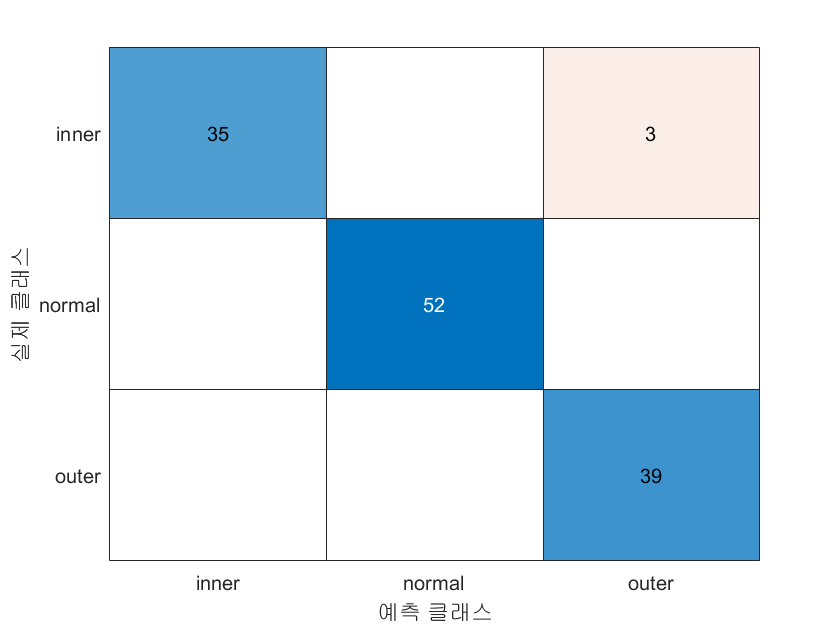


% Validate with CV-Test Set 
cm = confusionchart(sampleLabel,class);

### Predict test data

Predict the classification of test data (Xtest)

%%% YOUR CODE GOES HERE
% predictClass = predict(_______)

**Calculate the loss  of Test**

%%% YOUR CODE GOES HERE (Xtest,Ytest)
% L=loss(___________)


predictClass = 108×1 cell 배열
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}


**Plot  Confusion matrix of Test data**

figure

L = 0.0370


%%% YOUR CODE GOES HERE
% resubCM = confusionchart(____________);

**Plot  Test Results**

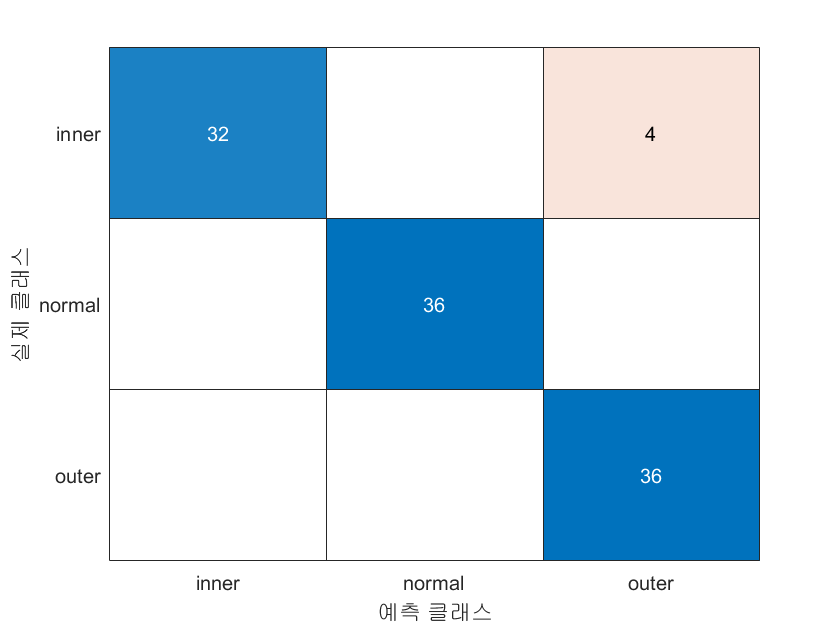

color = lines(6);               % Generate color values

figure
gscatter(X(:,1),X(:,2),Y, color(1:3,:))
hold on
gscatter(Xtest(:,1),Xtest(:,2),Ytest, color(4:6,:))
title('Test Data Clusters')
xlabel('Feature 1')
ylabel('Feature 2')

# LQA Classification 

fitdiscr()

### Fit QDA

qda = fitcdiscr(X,Y,'DiscrimType','quadratic');

### **Anlayze (All Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

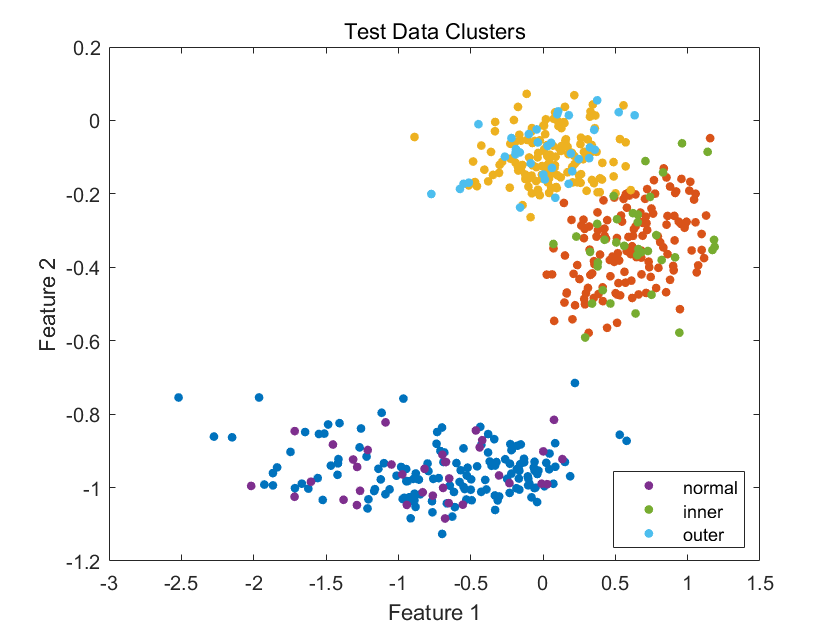

%%% YOUR CODE GOES HERE
% ldaResubErr = resubLoss(______)

**Confusion matrix** on the training set

qdaClass = resubPredict(qda);

figure
%%% YOUR CODE GOES HERE
% qdaResubCM = confusionchart(__________);


ldaResubErr = 0.0093

**Misclassification Plot**

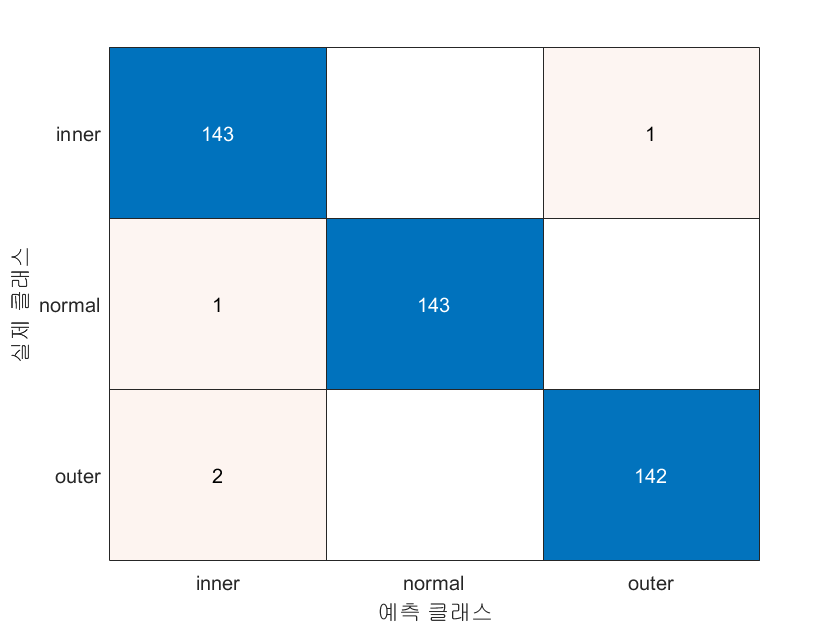

bad = ~strcmp(qdaClass,Y);

figure()
gscatter(X(:,1),X(:,2),Y)
hold on;

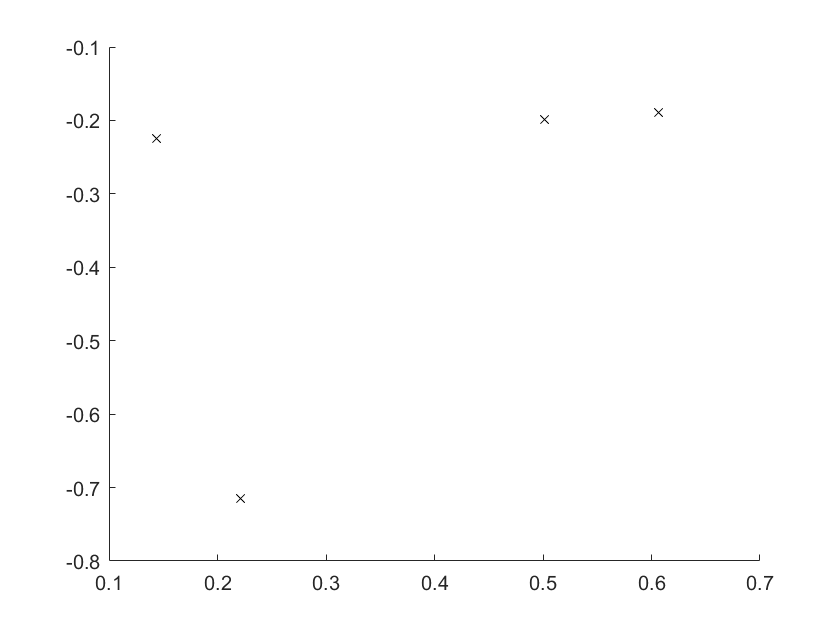

plot(X(bad,1), X(bad,2), 'kx');
xlabel('Feature 1')
ylabel('Feature 2')
hold off;


% Visualize Separation regions 
[x,y] = meshgrid(-4:.1:2,-1.2:.1:0.2);
x = x(:);
y = y(:);
j = classify([x y],X,Y,'quadratic');

gscatter(x,y,j,'grb','sod')

### **Validation (CV)**

Estimate the true test error  using 10-fold stratified cross-validation.

cvqda = crossval(qda,'CVPartition',cv);
qdaCVErr = kfoldLoss(cvqda)

### Predict test data

Predict the classification of test data

%%% YOUR CODE GOES HERE


**Calculate the loss  of Test**

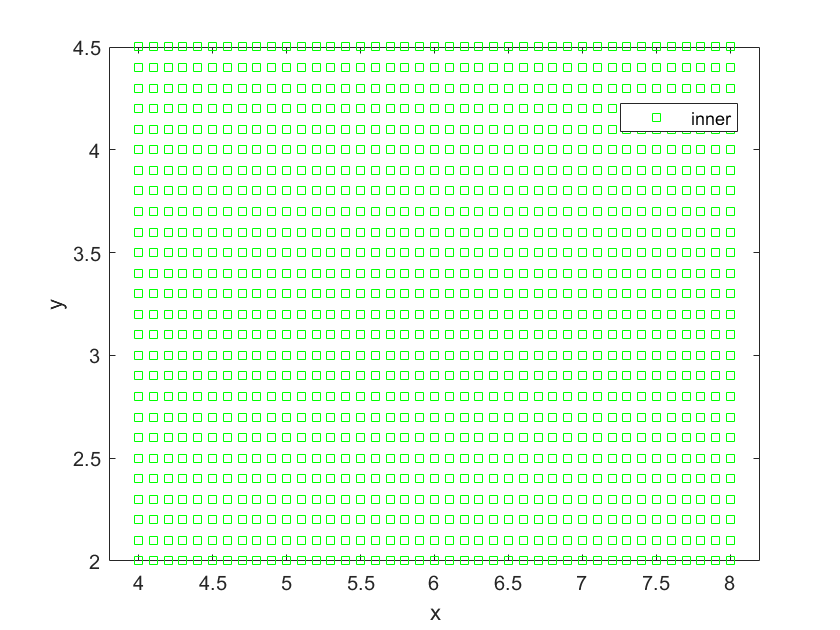

%%% YOUR CODE GOES HERE

**Plot  Confusion matrix of Test data**

%%% YOUR CODE GOES HERE


qdaCVErr = 0.0093

# Exercise

## Exercise 1: 

Now, Select any 3 features and repeat the process. 

**Features**

% Example
% X(:, 1) = table2array(glob_all_train(:, "kv"));       % Kurtosis value of time data
% X(:, 2) = table2array(glob_all_train(:, "mf"));       % Marginal-Factor
% X(:, 3) = table2array(glob_all_train(:, "cf"));       % Marginal-Factor

predictClass = 108×1 cell 배열
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}


Plot the test and train results in 3D graph.

L = 0

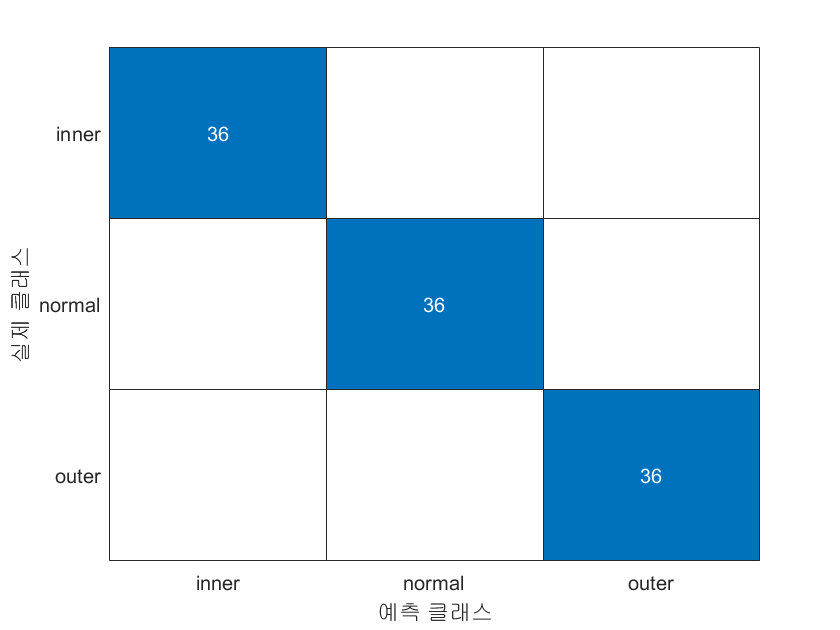

% Your code goes here
% Your code goes here

## Exercise 2 

Compare performance of Logistic Regression vs LDA vs LQA for CWRU dataset